# Rock vs No Rock: Data recording sheet

Author: Ross Wilkinson

University: University of Colorado Boulder

## Testing information

- Experiment: Rock vs No Rock

- Objective: Test effect of bicycle lean on maximal power output 

- Date: September 17, 2020

- Location: Locomotion Laboratory

- Subject: BL

- Quarq calibration factor: 333

## Experimental setup

### Protocol reminders

- Charge Garmin, iPad, and IMUs

- Clarify participant understanding and answer questions

- Set saddle height and handlebar position

- Sanitize bicycle

- Calibrate power meter

- Setup cooling fan

- Gift card and signature

### Experimental conditions

- Preferred Lean

- Self-restricted

- Locked

### Trial order

- Warm up: 5 min at ~100 W (3.5 lb)

- Familiarization: Standing and leaning (8.5 lb)

- Pmax Test: 3 x hanging weights under condition 1

- Block 1: Randomize

- Block 2: Randomize

- Block 3: Randomize

### Environmental conditions

- Temperature (C): 21.5

- Humidity (%): 49.9

- Pressure (mmHg): 636            

- Altitude (m): 1641

### Subject characteristics

Record subject characteristics to table for group data analysis.

number = 13;
code = {'BL'};
sex = {'M'};
age = 35;
mass = 180; %lb
height = 1.85; %m

T = table(number,code,sex,age,mass,height)

## Results

Use mass to calculate individualised hanging weights for Pmax Test.

listPerc = [0.06; 0.10; 0.14; 0.18];
listHang = listPerc * mass

### Pmax test

Record Pmax test results. Fit curve to predict optimal hanging weight.

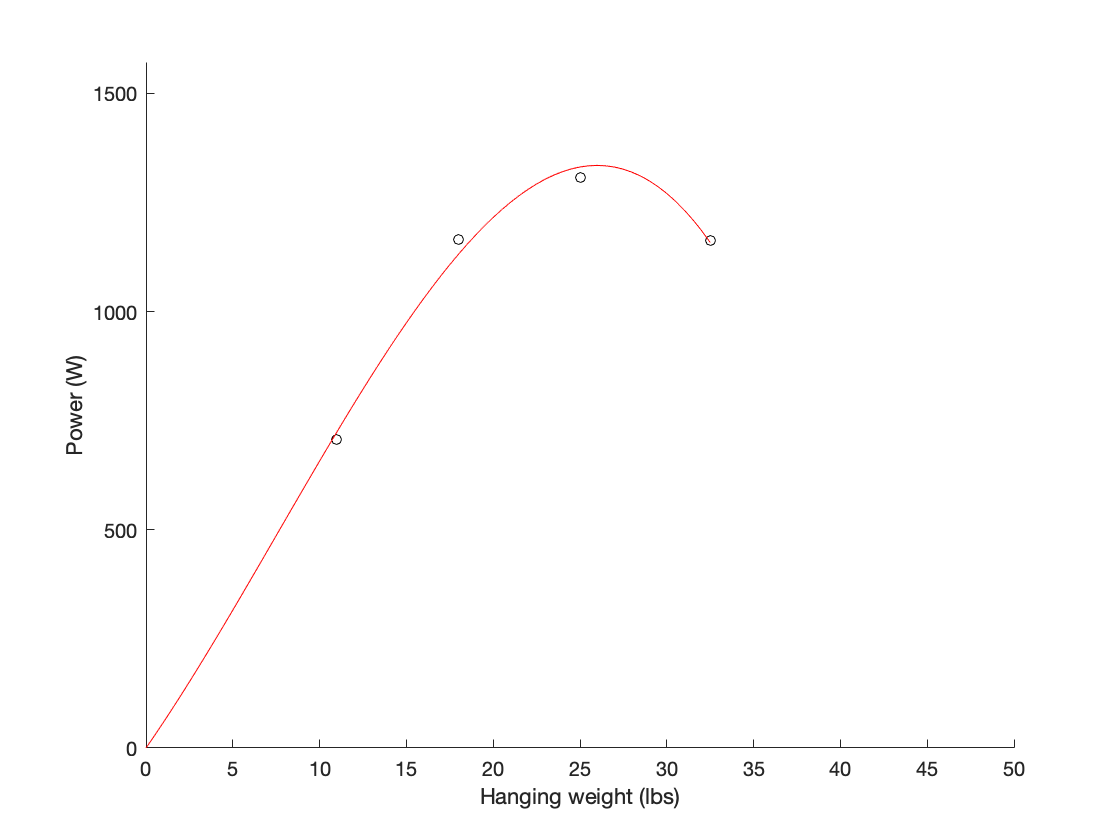

x = [11; 18; 25; 32.5]; % hanging weight
x_ = [168; 141; 117; 76]; % cadence
y = [706; 1165; 1308; 1164]; % power output

% fit curve: power vs hang
[c, ~, ~] = fit(x,y,'poly3','Lower',[-Inf -Inf -Inf 0],'Upper',[Inf Inf Inf 0]);
% [c, ~, ~] = fit(x,y,'poly2');

new_x = 0:max(x)/(max(x)*2):max(x);
new_y = c.p1*new_x.^3 + c.p2*new_x.^2 + c.p3*new_x + c.p4;

% plot curve
scatter(x,y,25,'k','filled');
hold on
plot(new_x,new_y,'k-')

% edit figure
box off
xlabel('Hanging weight (lbs)')
ylabel('Power (W)')
xlim([0 50])
ylim([0 max(y)*1.2])


% find optimal x and y
[yOpt,I] = max(new_y);
xOpt = new_x(I);

fprintf('Predicted maximal power output = %4.2f Watts \n', yOpt)

Predicted maximal power output = 1334.93 Watts 


fprintf('Predicted optimal hanging weight = %4.2f Lbs \n', xOpt)

Predicted optimal hanging weight = 26.00 Lbs 


### Randomize trial order within each block

randperm(3)

ans =      1     2     3


randperm(3)

ans =      3     1     2


randperm(3)

ans =      3     2     1


### Experimental results

Record results to array then convert to table.

data = [
    13, 1, 1, 25.5, 1361, 108;
    13, 2, 1, 25.5, 1357, 109;
    13, 3, 1, 25.5, 1392, 114;
    13, 3, 2, 25.5, 1425, 117;
    13, 1, 2, 25.5, 1335, 116;
    13, 2, 2, 25.5, 1336, 114;
    13, 3, 3, 25.5, 1418, 119;
    13, 2, 3, 25.5, 1320, 115;
    13, 1, 3, 25.5, 1352, 118;
    ];

T_ = array2table(data, ...
    'VariableNames',{'subject','condition','trial','hangingWeight','power','cadence'})

T_ = 9×6 table
    subject    condition    trial    hangingWeight    power    cadence
    _______    _________    _____    _____________    _____    _______

      13           1          1          25.5         1361       108  
      13           2          1          25.5         1357       109  
      13           3          1          25.5         1392       114  
      13           3          2          25.5         1425       117  
      13           1          2          25.5         1335       116  
      13           2          2          25.5         1336       114  
      13           3          3          25.5         1418       119  
      13           2          3          25.5         1320       115  
      13           1          3          25.5         1352       118  

## Data analysis

Calculate mean and SD power and cadence for experimental trials.

varfun(@mean,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    mean_power    mean_cadence
    _________    __________    __________    ____________

        1            3           1349.3            114   
        2            3           1337.7         112.67   
        3            3           1411.7         116.67   


varfun(@std,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    std_power    std_cadence
    _________    __________    _________    ___________

        1            3          13.204        5.2915   
        2            3          18.556        3.2146   
        3            3          17.388        2.5166   
